# Comparison Example Part 3: Analysis of the results and comparison

## Objective: 

In Part 3, the goal is to analyse the distribution fo the samples that is obtained from $\pi \left(\mathit{\mathbf{x}}\right)$ and $\pi_{\mathit{\mathbf{T}}} \left(\mathit{\mathbf{y}}\right)$ by each of the samplers. This comparison will be done in the basis of $\mathit{\mathbf{x}}$, meaning to say that the samples of $\mathit{\mathbf{y}}$ will have to undergo an inverse Affine-transformation. Details to this will be described later.

In essence, for a sampler to possess affine-invariant property, the distribution of samples from $\pi \left(\mathit{\mathbf{x}}\right)$ and that from $\pi_{\mathit{\mathbf{T}}} \left(\mathit{\mathbf{y}}\right)$ after undergoing inverse Affine-transformation should be identical. This implies that the sampler views both the poorly-scaled distribution $\pi \left(\mathit{\mathbf{x}}\right)$ and the Affine-transformed distribution $\pi_{\mathit{\mathbf{T}}} \left(\mathit{\mathbf{y}}\right)$ in the same footing in that it does not view one distribution being easier to sample from than the other.

For each sampler, we will be analysing its sample scatterplot profile against the analytical PDFs as well as comparing the Empirical CDFs (ECDFs) with the analytical marginal CDFs.

## 1) Load data from Part 1 and Part 2:

% Load the data from Example_Comparison_Part1.mlx:
load("Example_Comparison_Part1.mat")

% Load the data from Example_Comparison_Part2.mlx:
load("Example_Comparison_Part2.mat")

## 2) Generating the scatterplot profile:

### a i) Ensemble sampler: Scatterplot profile for $\pi \left(\mathit{\mathbf{x}}\right)$

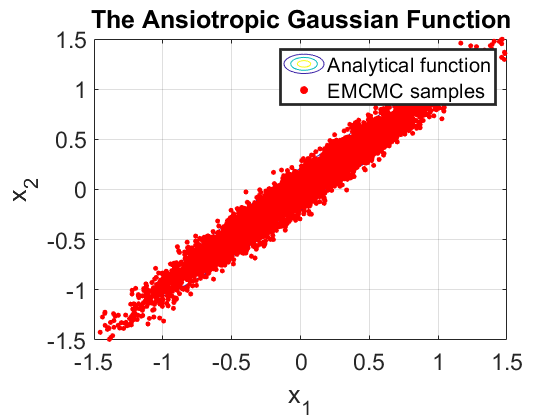

figure(); 
hold on; box on; grid on;
contour(X1,X2,exp(Z))
colormap(parula)
title('The Ansiotropic Gaussian Function')
xlim([-1.5 1.5])
ylim([-1.5 1.5])
scatter(samples_emcmc_1(:,1),samples_emcmc_1(:,2), 15, 'r.')
xlabel('x_1')
ylabel('x_2')
legend('Analytical function','EMCMC samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

### a ii) Ensemble sampler: Scatterplot profile for $\pi_T \left(\mathit{\mathbf{y}}\right)$

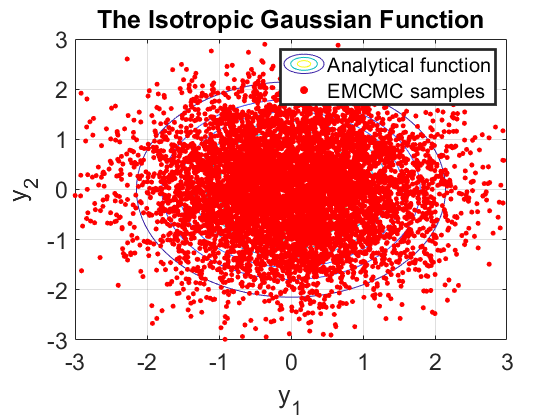

figure(); 
hold on; box on; grid on;
contour(Y1,Y2,exp(Z_scaled))
colormap(parula)
title('The Isotropic Gaussian Function')
xlim([-3 3])
ylim([-3 3])
scatter(samples_emcmc_2(:,1),samples_emcmc_2(:,2), 15, 'r.')
xlabel('y_1')
ylabel('y_2')
legend('Analytical function','EMCMC samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

### b i) Metropolis-Hastings sampler: Scatterplot profile for $\pi \left(\mathit{\mathbf{x}}\right)$

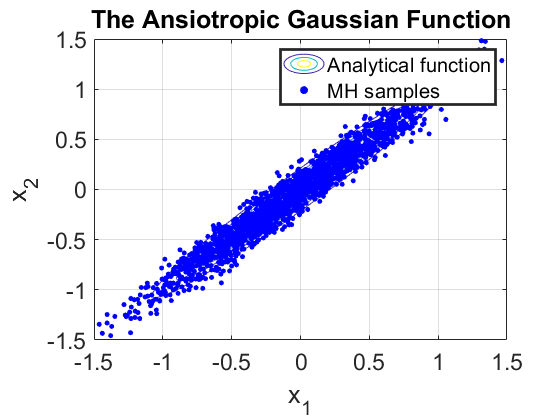

figure(); 
hold on; box on; grid on;
contour(X1,X2,exp(Z))
colormap(parula)
title('The Ansiotropic Gaussian Function')
xlim([-1.5 1.5])
ylim([-1.5 1.5])
scatter(samples_mh_1(:,1),samples_mh_1(:,2), 15, 'b.')
xlabel('x_1')
ylabel('x_2')
legend('Analytical function','MH samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

### b ii) Metropolis-Hastings sampler: Scatterplot profile for $\pi_T \left(\mathit{\mathbf{y}}\right)$

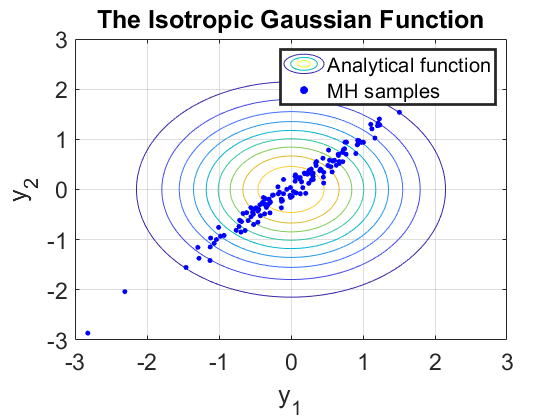

figure(); 
hold on; box on; grid on;
contour(Y1,Y2,exp(Z_scaled))
colormap(parula)
title('The Isotropic Gaussian Function')
xlim([-3 3])
ylim([-3 3])
scatter(samples_mh_2(:,1),samples_mh_2(:,2), 15, 'b.')
xlabel('y_1')
ylabel('y_2')
legend('Analytical function','MH samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

## 3) Generating the Empirical CDFs:

### a) Plot the Analytical Marginal CDFs for $x_1$and $x_2$:

% Defining the scaling factor of the target distribution:
e = 0.01; 

% Defining the target distribution in real space:
fun = @(x1,x2) exp(-((((x1 - x2).^2)./(2.*e)) + (((x1 + x2).^2)./(2))));

% Marginal PDF distribution of x1:
fun_x1 = @(x1) integral(@(x2) fun(x1,x2),-4,4);

% Marginal PDF distribution of x2:
fun_x2 = @(x2) integral(@(x1) fun(x1,x2),-4,4);

% To generate marginal CDFs for x1 and x2
fun_x1_out = zeros(1000,1); fun_x2_out = zeros(1000,1);
x1 = linspace(-4,4,1000); x2 = linspace(-4,4,1000);
for i = 1:1000
fun_x1_out(i) = fun_x1(x1(i)); 
fun_x2_out(i) = fun_x2(x2(i));
end

% Analytical marginal CDF for x1 (after normalization):
fun_x1_out = normalize(cumsum(fun_x1_out),'range',[0,1]);

% Analytical marginal CDF for x2 (after normalization):
fun_x2_out = normalize(cumsum(fun_x2_out),'range',[0,1]);

### b) Re-scaling samples of $y_1$ and $y_2$:

As mentioned in the introduction of this example file that the samples of $y_1$ and $y_2$ need to undergo inverse Affine-transformation back to $x_1$ and $x_2$ respectively. This is so as to ensure a fair comparison of the distribution between the samples of $\mathit{\mathbf{x}}$ obtained directly from $\pi \left(\mathit{\mathbf{x}}\right)$, and that obtained indirectly from $\pi_{\mathit{\mathbf{T}}} \left(\mathit{\mathbf{y}}\right)$.

The inverse Affine-transformation from $\mathit{\mathbf{y}}$ back to $\mathit{\mathbf{x}}$ is as such:


$$\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{\sqrt{\epsilon }}{2} & \frac{1}{2}\\
-\frac{\sqrt{\epsilon }}{2} & \frac{1}{2}
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack$$


This implies the following transformations:


$$\begin{array}{l}
x_1 =\frac{1}{2}\left(\sqrt{\epsilon }y_1 +x_2 \right)\\
x_2 =\frac{1}{2}\left(-\sqrt{\epsilon }y_1 +x_2 \right)
\end{array}$$


% Rescale Ensemble samplers obtained from Isotropic target distribution:
rescaled_gwmcmc = zeros(size(samples_emcmc_2,1),size(samples_emcmc_2,2)); % Initiate with empty array
rescaled_emcmc(:,1) = 0.5.*(sqrt(e).*samples_emcmc_2(:,1) + samples_emcmc_2(:,2));
rescaled_emcmc(:,2) = 0.5.*(samples_emcmc_2(:,2) - sqrt(e).*samples_emcmc_2(:,1));

% Rescale Metropolis-Hastings samplers obtained from Isotropic target distribution:
rescaled_mh = zeros(size(samples_mh_2,1),size(samples_mh_2,2)); % Initiate with empty array
rescaled_mh(:,1) = 0.5.*(sqrt(e).*samples_mh_2(:,1) + samples_mh_2(:,2));
rescaled_mh(:,2) = 0.5.*(samples_mh_2(:,2) - sqrt(e).*samples_mh_2(:,1));

### c i) Compare ECDF plots for samples obtained via Ensemble sampler:

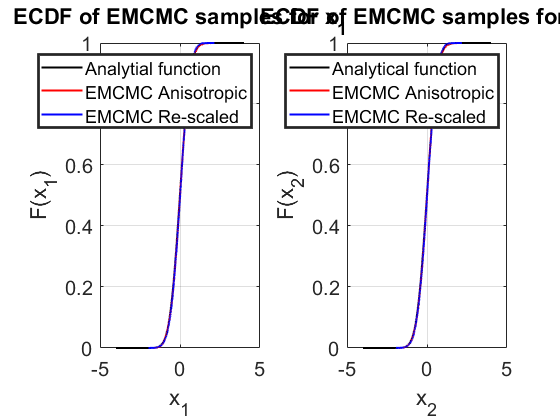

figure();
subplot(1,2,1)
hold on; box on; grid on;
plot(x1,fun_x1_out,'k','linewidth',1.5);
[f1a,x1a]=ecdf(samples_emcmc_1(:,1));
plot(x1a,f1a,'r','LineWidth',1.5)
[f1b,x1b]=ecdf(rescaled_emcmc(:,1));
plot(x1b,f1b,'b','LineWidth',1.5)
xlabel('x_1')
ylabel('F(x_1)')
legend('Analytial function', 'EMCMC Anisotropic', 'EMCMC Re-scaled', 'linewidth',2);
title('ECDF of EMCMC samples for x_1')
set(gca, 'Fontsize', 15)

subplot(1,2,2)
hold on; box on; grid on;
plot(x2,fun_x2_out,'k','linewidth',1.5);
[f2a,x2a]=ecdf(samples_emcmc_1(:,2));
plot(x2a,f2a,'r','LineWidth',1.5)
[f2b,x2b]=ecdf(rescaled_emcmc(:,2));
plot(x2b,f2b,'b','LineWidth',1.5)
xlabel('x_2')
ylabel('F(x_2)')
legend('Analytical function','EMCMC Anisotropic', 'EMCMC Re-scaled', 'linewidth',2);
title('ECDF of EMCMC samples for x_2')
set(gca, 'Fontsize', 15)

### c ii) Compare ECDF plots for samples obtained via MH sampler:

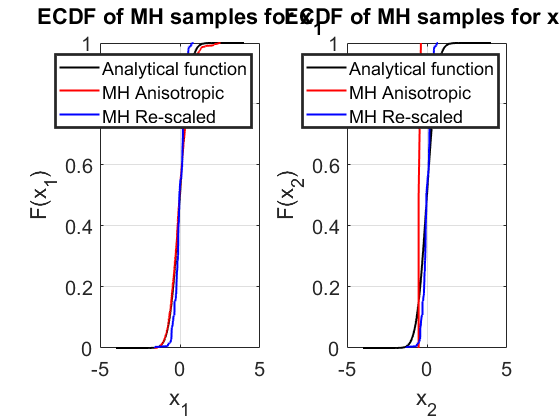

figure();
subplot(1,2,1)
hold on; box on; grid on;
plot(x1,fun_x1_out,'k','linewidth',1.5);
[f3a,x3a]=ecdf(samples_mh_1(:,1));
plot(x3a,f3a,'r','LineWidth',1.5)
[f3b,x3b]=ecdf(rescaled_mh(:,1));
plot(x3b,f3b,'b','LineWidth',1.5)
xlabel('x_1')
ylabel('F(x_1)')
legend('Analytical function','MH Anisotropic', 'MH Re-scaled', 'linewidth',2);
title('ECDF of MH samples for x_1')
set(gca, 'Fontsize', 15)

subplot(1,2,2)
hold on; box on; grid on;
plot(x2,fun_x2_out,'k','linewidth',1.5);
[f4a,x4a]=ecdf(samples_mh_1(:,2));
plot(x4a,f4a,'r','LineWidth',1.5)
[f4b,x4b]=ecdf(rescaled_mh(:,2));
plot(x4b,f4b,'b','LineWidth',1.5)
xlabel('x_2')
ylabel('F(x_2)')
legend('Analytical function','MH Anisotropic', 'MH Re-scaled', 'linewidth',2);
title('ECDF of MH samples for x_2')
set(gca, 'Fontsize', 15)

%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
